clear all
%% test1
omegai = [0 50 0];
tau    = 0.2;
Mv      = 30;
L2      = 10;
Na      = 5;
deltav  = 0.05;
si     = [0.3 0.4 floor(0.645/(deltav*tau))*deltav*tau];
%% test 2
omegai = [0 25 0];
tau    = 0.2;
Mv      = 30;
L2      = 10;
Na      = 5;
deltav  = 0.05;
si     = [0.3 0.4 floor(0.645/(deltav*tau))*deltav*tau];
%%test 3
omegai = [0 50 0];
tau    = 0.2;
Mv      = 30;
L2      = 10;
Na      = 5;
deltav  = 0.05;
si     = [0.1 0.4 floor(0.645/(deltav*tau))*deltav*tau];

%%test4
omegai = [0 50 0];
tau    = 0.2;
Mv      = 10;
L2      = 10;
Na      = 5;
deltav  = 0.05;
si     = [0.3 0.4 floor(0.645/(deltav*tau))*deltav*tau];

enable_constraints=1;

% [C, M, number_of_elements] = define_grid(omegai,si,tau,deltav,L2,Na,Mv,enable_constraints)
% 
% % terminal cost
% Jh = zeros(1,number_of_elements);
% [u,J] = dptv( M, C, Jh);
% [u_one,J_one] = showOneOptimalWay(u,J);
% [v_one,s_one] = decodev_s(si,tau,deltav,Mv,u_one);
% c = getC(v_one,s_one,tau,deltav)
% figure()
% hold on
% plot(v_one,"g")
% plot(s_one,"b-")
% plot(si,"rx")
% grid on;
% hold off
% legend("speed","optimal distance","wished distance")

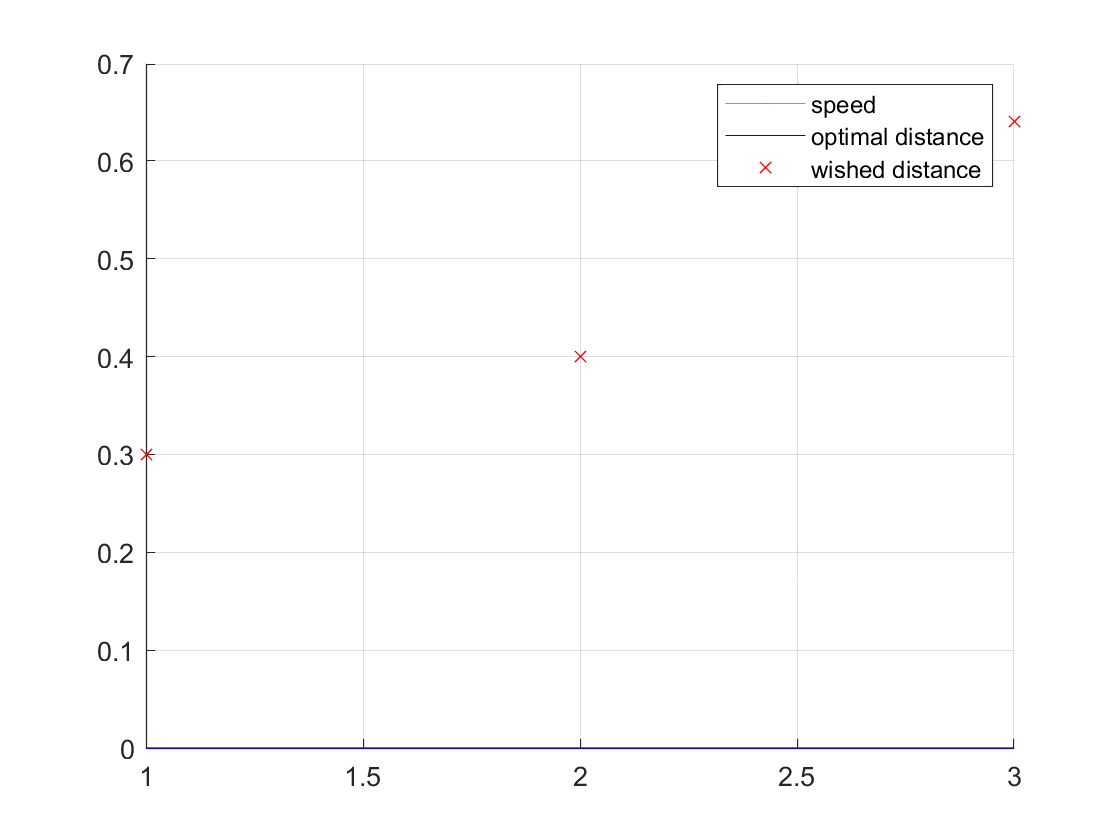

c =      0     0     0
     0     0     0


[c] = timeoptimalpathspeed2(omegai,si,tau,deltav,L2,Na,Mv)

function [u,J] = dptv( M, C, T)
h = length(M);
for l = 1:length(T)
    J_{h+1}{l} = T(l);
end
for k = h:-1:1
    ni = length(M{k}); % state dimension
    for i=1:ni
        nj = length(M{k}{i});
        caux = zeros(1,nj);
        for j = 1:nj
            caux(j) = C{k}{i}{j} + J_{k+1}{M{k}{i}{j}};
        end
        [a,b] = sort(caux);
        J_{k}{i} = a(1); J{k}{i} = J_{k}{i};
        u{k}{i}(1) = b(1);
        for ell = 2:length(a)
            if abs( a(ell) - a(1))<1e-8
                u{k}{i}(ell) = b(ell);
            else
                break;
            end
        end
    end
end

end


